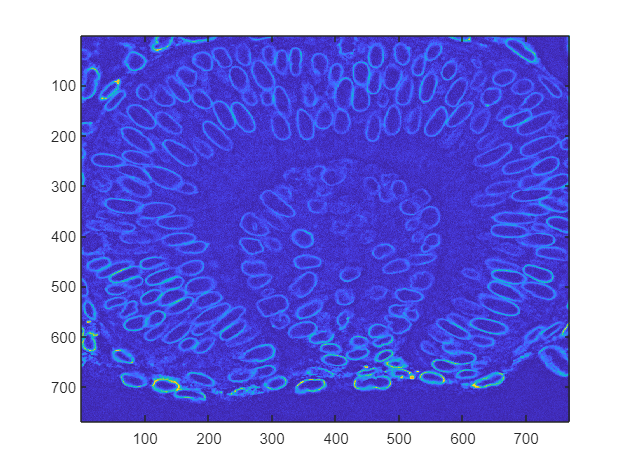

%Read in image and subtract background
img = imread('membrane_Image_2.tif');
bg = imopen(img,strel('disk',10));
img_bg = img-bg;
imagesc(img_bg)

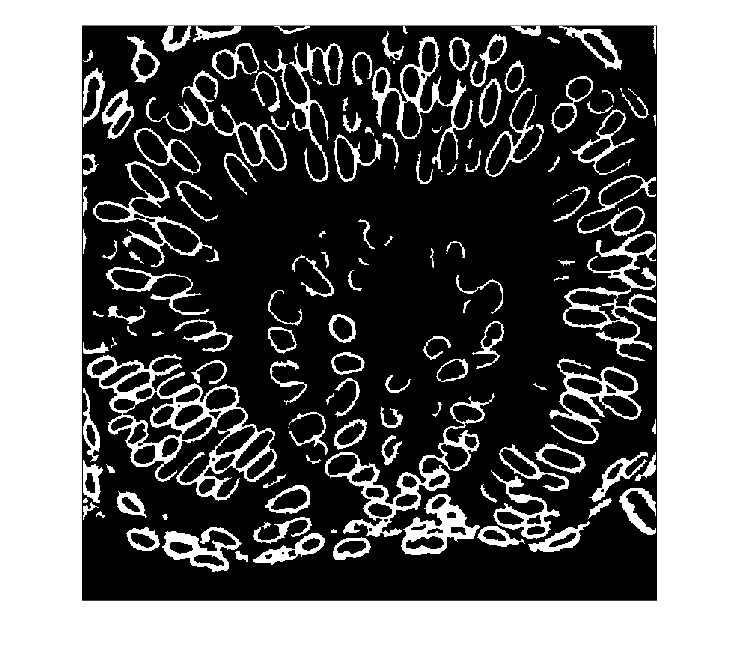

%Threshold and apply basic cleanup, this took a little trial and error since
%the example is so dim and noisy
bw = imbinarize(img_bg,'global');
bw = bwareaopen(bw,30);
bw = bwmorph(bw,'close',1);
bw = bwareaopen(bw,5);
imshow(bw)

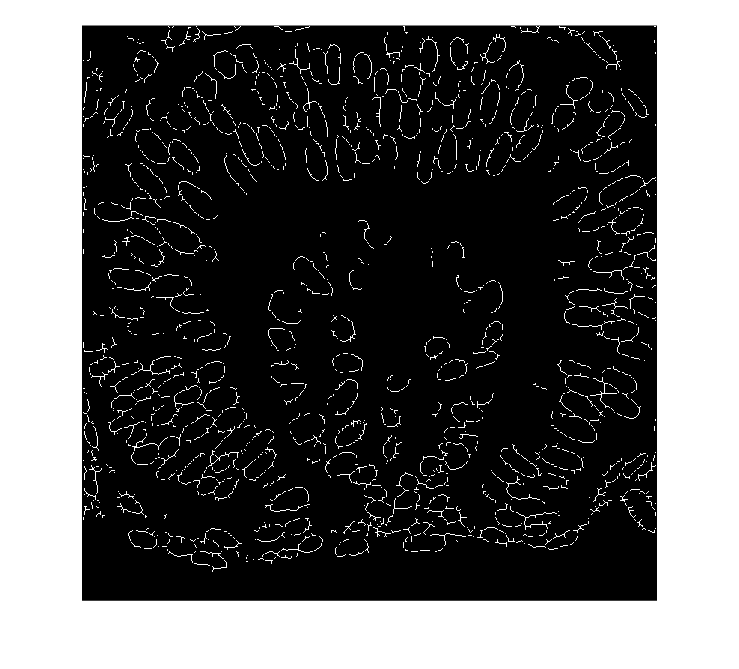

%Could we just skeletonize this to get clean boundaries?
skel = bwmorph(bw,'skel',inf);
imshow(skel)

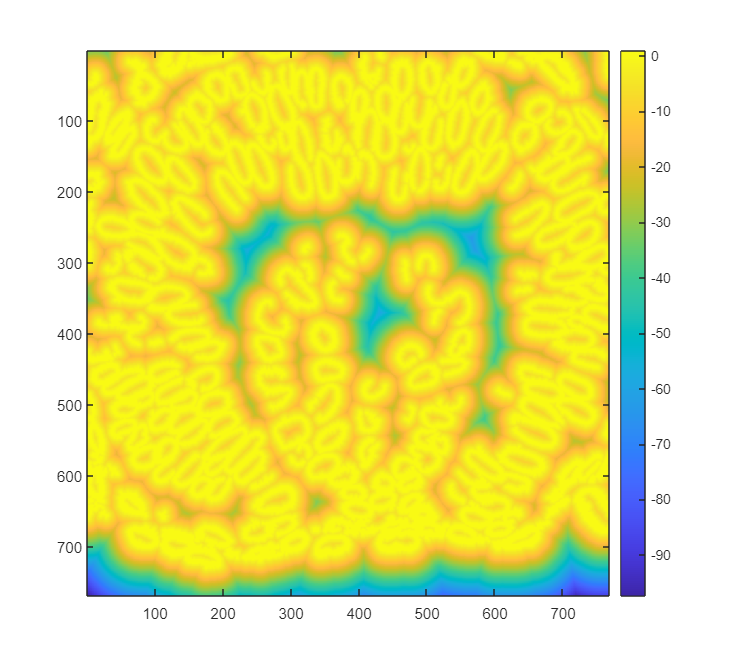

%Compute the distance transform and negate it. Here the cells themselves
%are technically the background, so we don't need to use ~bw
D = imcomplement(bwdist(bw));
imagesc(D)
colorbar

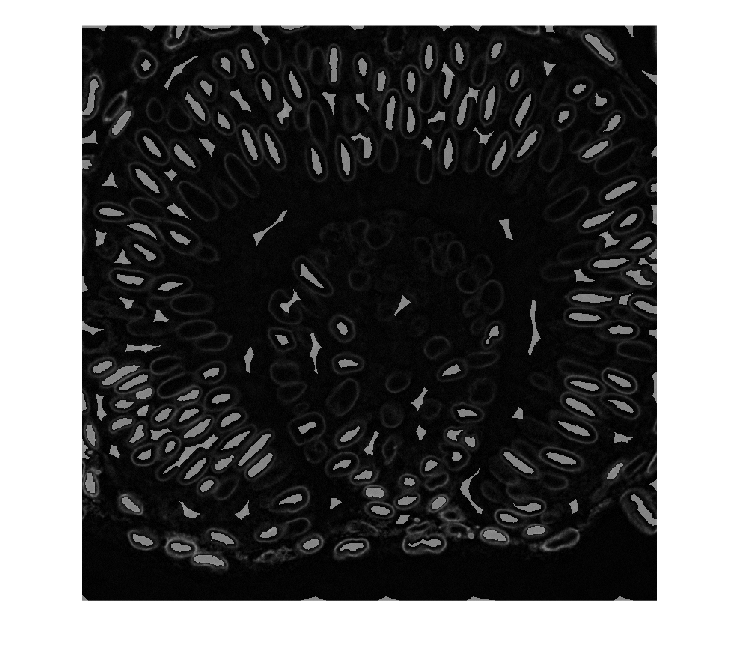

%imextendedmin finds all touching pixels that are a local minimum
%take the complement of img_log so that the centers are minima
mask = imextendedmin(D,5);
imshowpair(img_bg, mask,'blend')

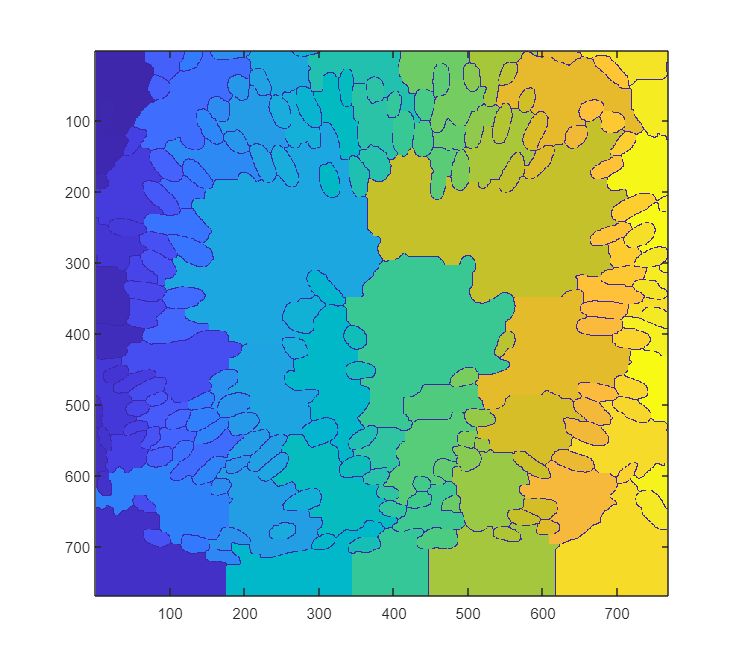

%imimposemin takes the local minima we found above and forces those to be
%the only minima in the original distance transform, ensuring that each
%will be the center of a region found by the watershed transform
D2 = imimposemin(D,mask);
Ld2 = watershed(D2);
imagesc(Ld2)

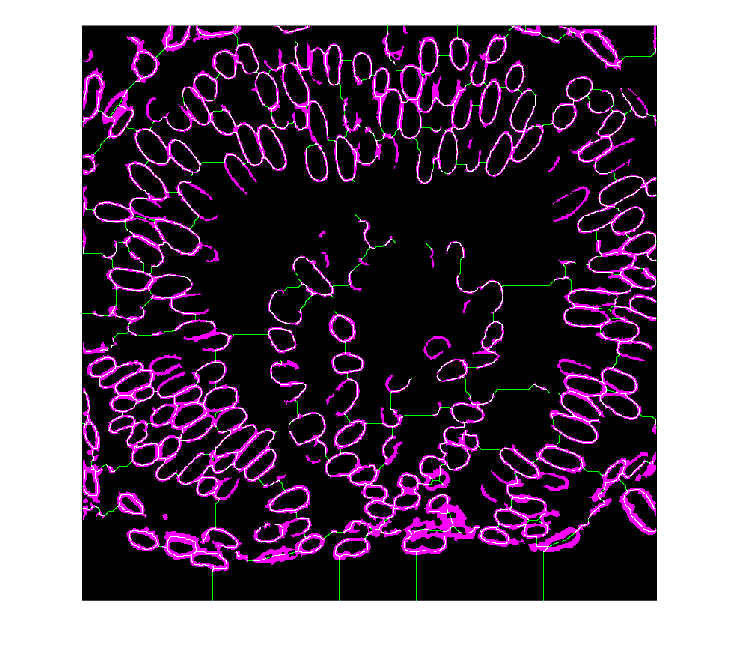


%We now find all pixels in the watershed transform that are = 0, these are
%the cell boundaries computed based on the watershed. The foreground
%objects in Ld2 correspond to the interior area of each cell!
bw2 = Ld2==0;
imshowpair(bw2,bw)